# **Live cell analysis**

Cell line: MCF10A, YFP-PCNA, NR45(pCW_Cdt1-mCherry)

Microscope: 3i 60x WI (C143) others 3i 60x Oil

Imaging:  2 min interval (C143) or 3 min interval for others

**Testing for:**

- Cdt1 degradation duration

- Cdt1 degradation relative to PCNA loading

**Annotations**

- Cdt1 degradation start

- Cdt1 low level time

- PCNA start (multiple thresholds)

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
clear S dat
%%% C143
conditions = {
        'all',1,1,1,[0 0 0]; %1   
};
dataDir = file_loc;
dat= load(['C143_data.mat'],'S');
dat = dat.S;
% dat = loadData_C143(conditions, dataDir);
dat.dataDir = file_loc;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/2;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C143';
S = dat;
S.POI(72,3) = S.POI(72,3) + 3;

%%% C173
conditions = {
        'all',1,1:8,1:8,[0 0 0]; %1   
};
dataDir = file_loc;
dat = load([dataDir filesep 'C173_data.mat'],'S');
dat = dat.S;
% clear dat
% dat = loadData_C173(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,10);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C173';
S = [S dat];

%%% C175
conditions = {
        'all',1:4,1:4,1:4,[0 0 0]; %1   
};
clear dat
dataDir = file_loc;
dat = load([dataDir filesep 'C175_data.mat'],'S');
dat = dat.S;
% dat = loadData_C175(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C175';
S = [S dat];

%%% C176
conditions = {
        'all',1:4,1:4,1:4,[0 0 0]; %1   
};
dataDir = file_loc;
dat = load([dataDir filesep 'C176_data.mat'],'S');
dat = dat.S;
% clear dat
% dat = loadData_C176(conditions, dataDir);
dat.dataDir = dataDir;
dat.POI(:,4) = dat.filterPOI(:,5);
dat.conditions = conditions;
dat.framesPerHr = 60/3;
dat.numFrames = size(dat.area,2);
dat.xFrames = 1:dat.numFrames;
dat.xTime = (dat.xFrames-1)./dat.framesPerHr;
dat.experiment = 'C176';
S = [S dat];

**Gate cells**

gates = [30 20 20 20];
filters = [5 7 5 5];
for c = 1:length(S)
    S(c).gate = false(length(S(c).area(:,1)),1);    
    for i = 1:length(S(c).area(:,1))
        if ~isnan(S(c).POI(i,3)) 
            if S(c).POI(i,3) + gates(c) <= S(c).numFrames 
                if S(c).sigNormAct(i,S(c).POI(i,3)+gates(c)) < .5 
                    S(c).gate(i) = true;
                end
            end
        end
        if S(c).POI(i,4) - 20 > 0
               pcna_pre = S(c).filterArea(i,(S(c).POI(i,4)-20):S(c).POI(i,4),filters(c));
               pcna_pre = sum(pcna_pre > 5);
                if pcna_pre >1
                    S(c).gate(i) = false;
                end
        end
    end
    disp(sprintf('%d cells left over after gate cond %d',sum(S(c).gate),c))
    
end

56 cells left over after gate cond 1
51 cells left over after gate cond 2
16 cells left over after gate cond 3
31 cells left over after gate cond 4


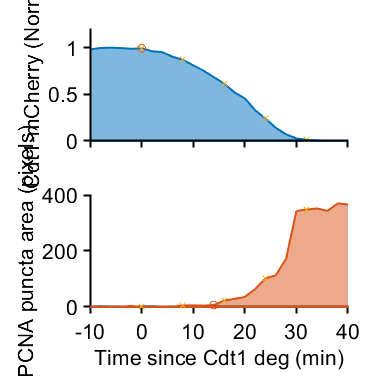

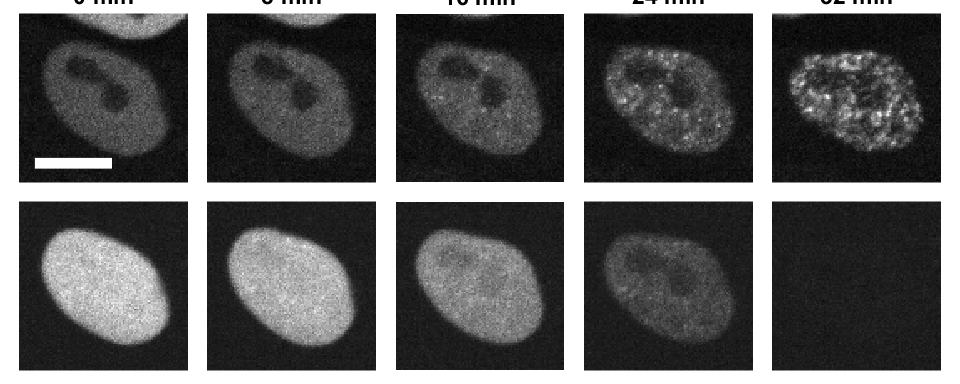

cond = 1;
rng(1)
maskpaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Mask\'};
impaths = {'F:\Data\C-Cdt1\Figures\Dryad\Data\C143-PCNA3i\Raw\'};
before = 0;
after = 16;
sizeBox = 50;
interval = 4;
num_cells = 20;
pcna_filter = 5;
pcna_plot = 3;
frames = (before+after)/interval +1;
pixel = .217; % micron/pixel
bar_length = 10;

inds = S(cond).gate &  ~isnan(S(cond).POI(:,3)) & ~isnan(S(cond).filterPOI(:,pcna_filter)) &  S(cond).POI(:,3) + after <= S(cond).traceStats(:,2)...
    & S(cond).POI(:,3) - before >= S(cond).traceStats(:,1) & S(cond).sigMax >150 & S(cond).sigMax < Inf;
% cells = find(inds);
cells = 72;
% rands = randsample(length(cells),min(num_cells,length(cells)));
rands =1;
for i = 1:length(cells(rands))
    c = cells(rands(i));
    %     S(cond).POI(c,3)
%     S(cond).filterPOI(c,pcna_filter)
    cdt1_start = S(cond).POI(c,3);
    startFrame = cdt1_start - before;
    endFrame = cdt1_start + after;
    f = startFrame:interval:endFrame;
    
    cols = lines(2);
    figure('Units','inches','Position',[0 0 4 4])
    title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
    tiledlayout(2,1)
    nexttile
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNormAct(c,:),'EdgeColor',cols(1,:),'FaceColor',cols(1,:),'FaceAlpha',.5,'LineWidth',1.5)
    hold on
    scatter(0,S(cond).sigNormAct(c,cdt1_start))
    scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNormAct(c,f),'x')
    ylim([0 1.2])
%     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
    xlim([-10 40])
    box off
    xticklabels([])
    xticks([-10:10:40])
    ylabel('Cdt1-mCherry (Norm)')

    nexttile
    hold on
    area(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).filterArea(c,:,pcna_plot),'EdgeColor',cols(2,:),'FaceColor',cols(2,:),'FaceAlpha',.5,'LineWidth',1.5)
    scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_plot))
    scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_plot),'x')
    ylabel('PCNA puncta area (pixels)')
    xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
    xticks([-10:10:40])

    xlim([-10 40])
     print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

%     figure('Units','inches','Position',[0 0 4 4])
%     title(sprintf('Cell: %d, %d, max %.0f',cond,c,S(cond).sigMax(c)))
%     yyaxis left
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).sigNormAct(c,:))
%     hold on
%     scatter(0,S(cond).sigNormAct(c,cdt1_start))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).sigNormAct(c,f),'x')
%     ylim([0 1.2])
% %     xlim(60*[min((f-cdt1_start - 4)/S(cond).framesPerHr) 2])
%     xlim([-10 40])
%     ylabel('Cdt1-mCherry (Norm)')
%     yyaxis right
%     
%     plot(60*(S(cond).xFrames-cdt1_start)/S(cond).framesPerHr, S(cond).filterArea(c,:,pcna_filter))
%     scatter(60*(S(cond).filterPOI(c,pcna_filter)-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,S(cond).filterPOI(c,pcna_filter),pcna_filter))
%     scatter(60*(f-cdt1_start)/S(cond).framesPerHr,S(cond).filterArea(c,f,pcna_filter),'x')
%     ylabel('PCNA puncta area (pixels)')
%     xlabel('Time since Cdt1 deg (min)')
%     pbaspect([1 1 1])
%      print_pdf([pwd() '\Figs\' num2str(cond) '_montage_trace_cell_' num2str(c) 'final.pdf'])

    shot = S(cond).shot{c};
    im1path = [maskpaths{cond} shot '\' shot '_Mask_'];
    im2path = [impaths{cond} shot '\' shot '_YFP_'];
    im3path = [impaths{cond} shot '\' shot '_RFP_'];   
    
    f2 = figure('Units','inches','Position',[0 0 frames*2 2*2]);    

    for j=1:length(f)
        t = f(j);
        im1 = imread([im1path num2str(t) '.tif']);
        im2 = imread([im2path num2str(t) '.tif']);
        im3 = imread([im3path num2str(t) '.tif']);
        
        if cond == 1
            im2 = im2(50:4600,50:4600);
            im3 = im3(50:4600,50:4600);
        end
        
        x = S(cond).pos(c,t,1) - S(cond).jitters(c,t,1);
        y = S(cond).pos(c,t,2) - S(cond).jitters(c,t,2);

        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
%         im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        
        figure(f2)
        subplot_tight(2,frames,j,[.02 .02])
        imshow(im2crop,[80 500])
        title([num2str(60*(t-cdt1_start)/S(cond).framesPerHr) ' min'])
        if j==1
            maxval = max(im3crop(:));
            hold on
            plot([10 10 + bar_length/pixel],[90 90],'w','LineWidth',8)
        end
        subplot_tight(2,frames,j + frames,[.02 .02])
        imshow(im3crop,[50 maxval])
        
        cdt1_im = mat2gray(im3crop,[50 double(maxval)]);
        cdt1_im = cat(3,cdt1_im,cdt1_im,cdt1_im);
        
        pcna_im = mat2gray(im2crop,[80 500]);
        pcna_im = cat(3,pcna_im,pcna_im,pcna_im);        
        
        imwrite(pcna_im, [pwd() '\Figs\ind_PCNA_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])
        imwrite(cdt1_im, [pwd() '\Figs\ind_Cdt1_' num2str(cond)  '_montage_image_' num2str(c) '_' num2str(t) '.tiff'])

    end
   print_pdf([pwd() '\Figs\' num2str(cond)  '_montage_image_' num2str(c) 'final.pdf'])

    
end

**PCNA vs Cdt1 deg time scatter plot**

conds = [1 2 3 4];
figure('pos',[10 10 length(conds)*300 400 ]),
for i = 1:length(conds)
    subplot(1,length(conds),i), hold on
    inds = S(conds(i)).gate;
    cdt1_deg = (S(conds(i)).POI(inds,3)/S(conds(i)).framesPerHr) * 60;
    pcna = (S(conds(i)).POI(inds,4)/S(conds(i)).framesPerHr) * 60;
    scatter(cdt1_deg, pcna)
    plot([0 200], [0 200], 'k')
    p = robustfit(cdt1_deg, pcna)
    plot([0 200],[0 200]*p(2) + p(1))
    xlabel('Cdt1 degradation time')
    ylabel('PCNA time')
end

p =    15.9034
    0.9755


p =     7.9277
    1.0894


p =    19.2574
    1.0401


p =    17.9816
    1.0722


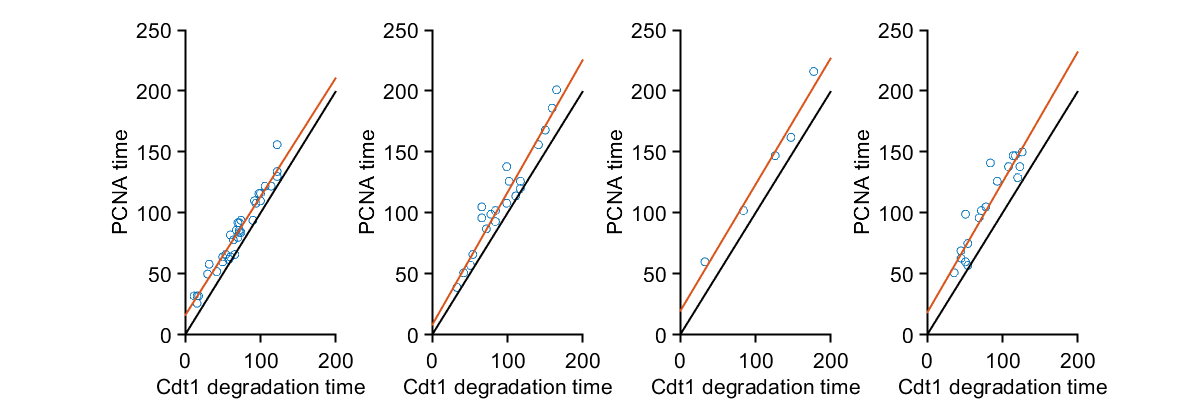

hold off

**Plot degradation times**

rng(1)
conds = [ 1 2];
all_cond = [];
all_num = [];
all_POI = [];
all_POI_PCNA = [];
all_maxSig = [];
all_time = [];
all_timePCNA = [];
all_timeBetween = [];
all_poi_time = [];
all_poi_pcna_time = [];

thresh = 0.05;
for j = 1:length(conds)
    cond = conds(j);
    inds = ~isnan(S(cond).POI(:,3)) &  S(cond).gate;
    dataSig = S(cond).sigNuc(inds,:);
    pcnaSig = S(cond).filterArea(inds,:,2);
    pcnaNuc = max(S(cond).pcnaNuc(inds,:),[],2);
    POI = S(cond).POI(inds,3);
    POI_PCNA = S(cond).POI(inds,4);
%     POI_PCNA = S(cond).filterPOI(inds,4);
    maxSig = NaN * ones(size(POI));
    time = NaN * ones(size(POI));
    timePCNA = NaN * ones(size(POI));
    timeBetween = NaN * ones(size(POI));
    low = NaN * ones(size(POI));
    
%     traces = S(cond).sigNormAct(inds,:);
    for i = 1:length(POI)
        trace_total_smooth = nansmoothm(dataSig(i,:),5, 'sgolay');
        min_trace = min(trace_total_smooth(POI(i):min([POI(i)+30,S(cond).numFrames])));
        trace_total_smooth = trace_total_smooth - min_trace;
        trace_norm = trace_total_smooth / trace_total_smooth(POI(i));
        trace = trace_norm(POI(i):end);
        maxSig(i) = max(dataSig(i,POI(i):end));
        low_point = find(trace <thresh,1,'first');
        if ~isempty(low_point)
            interpY = [-1 0] + low_point;
            interpX = trace(interpY);
            low_point_interp = interp1(interpX, interpY, thresh);
            low(i) = low_point_interp + POI(i) -1;
            time(i) = low_point_interp / S(cond).framesPerHr * 60;
            timePCNA(i) =  (POI(i) - POI_PCNA(i) + low_point_interp)/ S(cond).framesPerHr * 60;
            timeBetween(i) = (POI_PCNA(i) - POI(i))/S(cond).framesPerHr * 60;   
%             
%             if timeBetween(i) > 20
%                 figure
%                 yyaxis left
%                 hold on
%                 plot(trace_norm)
%                 scatter(POI(i),trace_norm(POI(i)))
%                 yyaxis right
%                 hold on
%                 plot(pcnaSig(i,:))
%                 if ~isnan(POI_PCNA(i))
%                     scatter(POI_PCNA(i), pcnaSig(i,POI_PCNA(i)))
%                 end
%                 pcnaNuc(i)
%             end
        end
    end
    
    all_cond = [all_cond; repmat(string(S(cond).experiment),size(POI))];
    all_num = [all_num; repmat(cond, size(POI))];
    all_POI = [all_POI; POI ];
    all_POI_PCNA = [all_POI_PCNA; POI_PCNA];
    all_maxSig = [all_maxSig; maxSig];
    all_time = [all_time; time];
    all_timePCNA = [all_timePCNA; timePCNA];
    all_timeBetween = [all_timeBetween; timeBetween];
    all_poi_time = [all_poi_time; POI / S(cond).framesPerHr];
    all_poi_pcna_time = [all_poi_pcna_time; POI_PCNA / S(cond).framesPerHr];
    
    
    figure('Position',[0 0 300*3 300])
    subplot(1,3,1), hold on
    scatter(maxSig,time)
    p = robustfit(maxSig,time)
    plot([0 500],[0 500]*p(2) + p(1))
    ylim([0 80])
    xlabel('Max Cdt1 expression')
    ylabel('Time Cdt1 deg')
    title(sprintf('X inters. %.1f min',p(1)))
    
    subplot(1,3, 2), hold on
    scatter(maxSig, timePCNA)
    p = robustfit(maxSig,timePCNA)
    plot([0 500],[0 500]*p(2) + p(1))
    ylim([0 80])
    xlabel('Max Cdt1 expression')
    ylabel('Time PCNA overlap')
    title(sprintf('X inters. %.1f min',p(1)))
    
    subplot(1,3, 3), hold on
    scatter(maxSig, timeBetween)
    p = robustfit(maxSig,timeBetween)
    plot([0 500],[0 500]*p(2) + p(1))
    ylim([0 80])
    xlabel('Max Cdt1 expression')
    ylabel('Time Between Cdt1 start PCNA start')
    title(sprintf('X inters. %.1f min',p(1)))
    
   
end

p =    24.6133
    0.0220


p =    10.2063
    0.0268


p =    13.7339
    0.0023


p =    28.3018
    0.0485


p =    12.8548
    0.0313


p =    13.7304
    0.0162



df = table(all_cond, all_num, all_POI, all_POI_PCNA, all_maxSig, all_time, all_timePCNA, all_timeBetween, all_poi_time, all_poi_pcna_time);
df.Properties.VariableNames = {'experiment', 'cond', 'poi', 'poi_pcna', 'max_sig', 'cdt1_deg', 'pcna_overlap','pcna_offset','poi_time','poi_pcna_time'};
[~, out1] = rmoutliers(df.cdt1_deg);
[~, out2] = rmoutliers(df.pcna_overlap);
[~, out3] = rmoutliers(df.pcna_offset);

    
figure,
df_plot = df(df.max_sig < 400 & df.max_sig > 10 & df.cdt1_deg < 60,:);
dataY = [df_plot.cdt1_deg; df_plot.pcna_overlap; df_plot.pcna_offset] ;
dataX = [repmat(1, size(df_plot.cdt1_deg)); repmat(2, size(df_plot.pcna_overlap)); repmat(3, size(df_plot.pcna_offset))];
% notBoxPlot(dataY, dataX)
% ylabel('Time (min)')
% set(gca,'XTickLabel',{'Cdt1 deg', 'PCNA overlap', 'Cdt1 deg - PCNA'},'XTickLabelRotation',45)

n = [];
m = [];
n(1) = sum(~isnan(df_plot.cdt1_deg));
n(2) = sum(~isnan(df_plot.pcna_overlap));
n(3) = sum(~isnan(df_plot.pcna_offset));

m(1) = nanmean(df_plot.cdt1_deg);
m(2) = nanmean(df_plot.pcna_overlap);
m(3) = nanmean(df_plot.pcna_offset);

sem(1) = tinv(.95,n(1)-1) * nanstd(df_plot.cdt1_deg)/sqrt(n(1));
sem(2) = tinv(.95,n(2)-1) * nanstd(df_plot.pcna_overlap)/sqrt(n(2));
sem(3) = tinv(.95,n(3)-1) * nanstd(df_plot.pcna_offset)/sqrt(n(3));

sprintf('Cdt1 deg time: %.1f-%.1f',m(1)-sem(1),m(1)+sem(1))

ans = 'Cdt1 deg time: 30.6-33.1'

sprintf('PCNA overlap time: %.1f-%.1f',m(2)-sem(2),m(2)+sem(2))

ans = 'PCNA overlap time: 13.5-16.4'

sprintf('PCNA offset: %.1f-%.1f',m(3)-sem(3),m(3)+sem(3))

ans = 'PCNA offset: 13.2-17.1'


% figure
% beeswarm(dataX(~isnan(dataY)),dataY(~isnan(dataY)),'sort_style','up');
% hold on
% errorbar([1 2 3],m,sem,'+k','LineWidth',1)
% ylabel('Time (min)')
% xticks([1:3])
% xlim([0 4])
% set(gca,'XTickLabel',{'Cdt1 deg', 'PCNA overlap', 'Cdt1 deg - PCNA'},'XTickLabelRotation',45)
dataY = [df_plot.cdt1_deg; df_plot.pcna_overlap] ;
dataX = [repmat(1, size(df_plot.cdt1_deg)); repmat(2, size(df_plot.pcna_overlap))];

figure('Units', 'Inches', 'Position', [0, 0, 3, 4])
h = violinPlot(dataY,'groups',dataX, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
xticklabels({'Cdt1 deg', 'PCNA overlap', 'Cdt1 deg - PCNA'})
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(dataX)) + .1;
scatter(dataX+jit, (dataY), 10,'k','filled','MarkerFaceAlpha',.5);
errorbar([1 2]+.25, m(1:2), sem(1:2),'+r','LineWidth',1.5)
ylabel('Time (min)')
% ylim([0 40])
yticks([0:10:60])
xlabel(' ')
% xtickangle(45)
% pbaspect([.66 1 1])
n = sum(~isnan(dataY) & dataX == 1)

n = 99

n = sum(~isnan(dataY) & dataX ==2)

n = 54

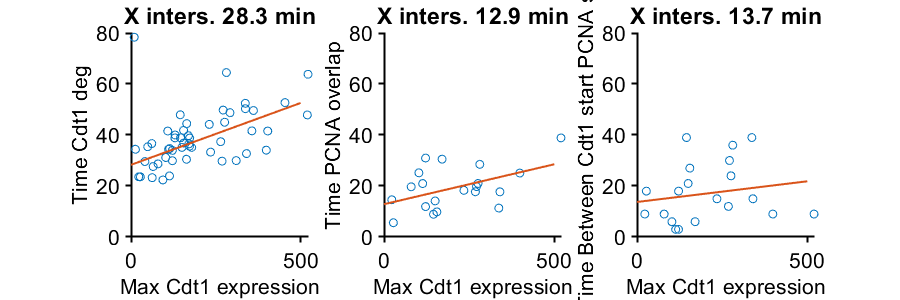

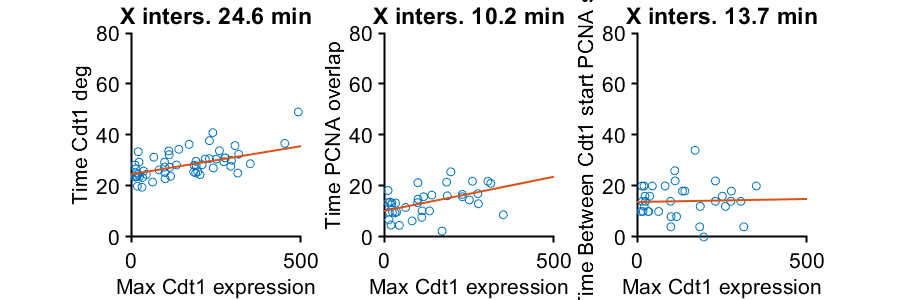

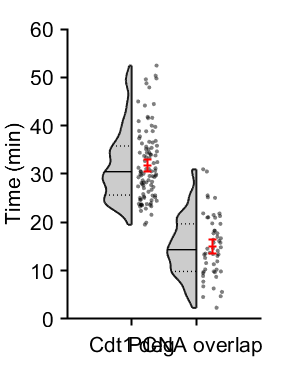

print_pdf([pwd() '\Figs\time_comparison.pdf'])


dataY = [df_plot.pcna_offset] ;
dataX = [repmat(1, size(df_plot.pcna_offset))];

figure('Units', 'Inches', 'Position', [0, 0, 2.5, 4])
h = violinPlot(dataY,'groups',dataX, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
xticklabels({'Cdt1 - PCNA', 'PCNA overlap', 'Cdt1 deg - PCNA'})
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(dataX)) + .1;
scatter(dataX+jit, (dataY), 10,'k','filled','MarkerFaceAlpha',.5);
errorbar([1]+.25, m(3), sem(3),'+r','LineWidth',1.5)

ylabel('Time (min)')
% ylim([0 60])
yticks([0:10:60])
% xtickangle(45)
% pbaspect([.5 1 1])
xlabel(' ')
n = sum(~isnan(dataY) & ~isnan(dataX))

n = 54

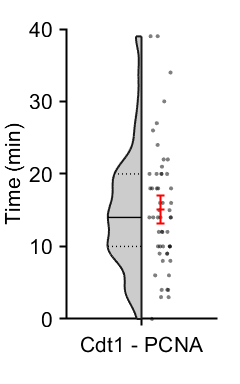

print_pdf([pwd() '\Figs\time_pcna_offset.pdf'])



figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
hold on

scatter(df_plot.poi_time, df_plot.poi_pcna_time,20,'filled','MarkerFaceAlpha',.5)
ylim([0 4])
xlim([0 4])
p = robustfit(df_plot.poi_time, df_plot.poi_pcna_time)

p =     0.2283
    1.0095


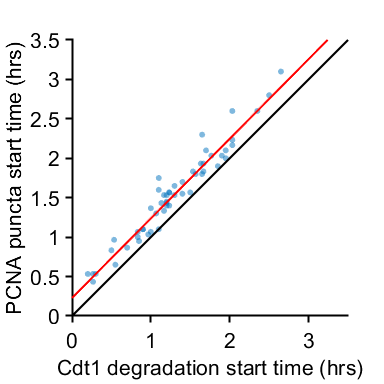

r =refline(p(2),p(1));
r.Color = 'r';
r = refline(1,0);
r.Color = 'k';
ylim([0 3.5])
xlim([0 3.5])
xlabel('Cdt1 degradation start time (hrs)')
ylabel('PCNA puncta start time (hrs)')
axis square
print_pdf([pwd() '\Figs\time_cdt1_pcna.pdf'])

n = sum(~isnan(df_plot.poi_time) & ~isnan(df_plot.poi_pcna_time))

n = 54